# Figure S7F, S7G

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'F040_data.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 20×5 cell array
    {'NR75 DMSO DMSO'     }    {[1 2 3 4]}    {[ 2]}    {[1]}    {[0 0 0]}
    {'NR75 DMSO TAK'      }    {[1 2 3 4]}    {[ 3]}    {[1]}    {[0 0 0]}
    {'NR75 DMSO RO'       }    {[1 2 3 4]}    {[ 4]}    {[1]}    {[0 0 0]}
    {'NR75 DMSO TAK/RO'   }    {[1 2 3 4]}    {[ 5]}    {[1]}    {[0 0 0]}
    {'NR75 DMSO TAK/RO/2i'}    {[1 2 3 4]}    {[ 6]}    {[1]}    {[0 0 0]}
    {'NR75 DOX DMSO'      }    {[1 2 3 4]}    {[ 7]}    {[1]}    {[0 0 0]}
    {'NR75 DOX TAK'       }    {[1 2 3 4]}    {[ 8]}    {[1]}    {[0 0 0]}
    {'NR75 DOX RO'        }    {[1 2 3 4]}    {[ 9]}    {[1]}    {[0 0 0]}
    {'NR75 DOX TAK/RO'    }    {[1 2 3 4]}    {[10]}    {[1]}    {[0 0 0]}
    {'NR75 DOX TAK/RO/2i' }    {[1 2 3 4]}    {[11]}    {[1]}    {[0 0 0]}
    {'NR77 DMSO DMSO'     }    {[5 6 7 8]}    {[ 2]}    {[1]}    {[0 0 0]}
    {'NR77 DMSO TAK'      }    {[5 6 7 8]}    {[ 3]}    {[1]}    {[0 0 0]}
    {'NR77 DMSO RO'       }    {[5 6 7 8]}    {[ 4]}    {[1]}    {[0 0 



framesPerHr = 60/12;
frameDrugAdded = 11;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

drug_time = frameDrugAdded/framesPerHr;

CCNA_row = [1 2 3 8];
CCNE_row = [4 5 6 7];
ALL_row = [1:8];

**Gate cells**

xthresh = 2e6;
xrange = linspace(0,5e6,1000);
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange);
    xi_trunc = xi(xi<xthresh);
    f_trunc = f(xi<xthresh);
    [~, maxi] = max(f_trunc);
    N_peak = xi_trunc(maxi);
    S(i).DNA_peak = N_peak;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .01;
        end


    end
    S(i).apcExpressGate = apcExpressGate;


end

S7F

ans = 700

ans = 196

ans = 1508

ans = 116

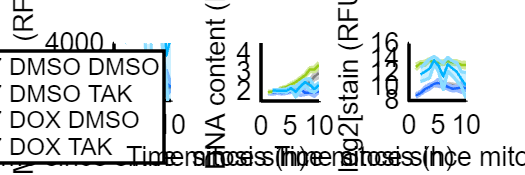

conds=[11 12 16 17] ;
poi_list = [1];


gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
name = {'since mitosis'};
edges = (0:(4/framesPerHr):15);
lims = {[0 10]};
gate_col = CCNE_row;



name_mean = [];

stain_lims = [8 16];

plot_IF_linear_gate_save(poi_list, conds, S, gateVals, rangeVals, edges, lims, name, conditions, gate_col,1, name_scatter, name_mean, stain_lims);

S7G

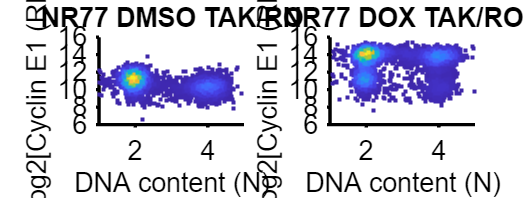

ans = 6410

ans = 6431

conds=[14 19];

xval = 'DNA';
yval = 'FarRed2';
row_gate = CCNE_row;

f1 = figure('pos', [10 10 length(conds)*400 300]);

for i = 1:length(conds)
    condition = conds(i);
    xdata = 2*(allIF(condition).(xval)/S(condition).DNA_peak);
    ydata =  real(log2(allIF(condition).(yval)));
    
    ind = any(allIF(condition).fixedRow == row_gate,2) & xdata > 0 & xdata < 5;
    sum(ind)
    xdata = xdata(ind);
    ydata = ydata(ind);
    
    figure(f1)
    subplot(1,length(conds),i)
    dscatter(xdata,ydata);
    xlim([1 5])
    ylim([6 16]);
    ylabel('log2[Cyclin E1 (RFU)]');
    xlabel('DNA content (N)');
    title(conditions{condition,1});
end


  % print_pdf(['Fig_S7G.pdf'])


function plot_IF_linear_gate_save(poi_list, conds, S, gateVals, rangeVals, edges, lims, name, conditions, col_gate, gate_stain, save_scatter, save_mean, stain_lims)
colors = [.5 .5 .5 ;.1 .4 1;.6 .8 .1; 0 .7 1];
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
    f0 = figure('units','inches','pos',[0 0 4*length(conds) 3*4 ]);
    f1 = figure('units','inches','pos',[0 0 4*3 4 ]);
    
    legend_names = {};
    for i=1:length(conds)
        
        ind= any(S(conds(i)).fixedRow == col_gate,2) & ~isnan(S(conds(i)).dna) & ~isnan(S(conds(i)).POI_time(:,poiAligned)) & S(conds(i)).apcExpressGate   & ...
            gate_vals(S(conds(i)), gateVals{i}, rangeVals{i}) ;
        
        xdata = S(conds(i)).POI_time(ind,poiAligned);
        ydata = [];
      
        ydata(:, 1) = S(conds(i)).FarRed2(ind);
        
        ydata(ydata(:,1) < .1,1) = .1;
        ydata(:,1) = (ydata(:,1));
        ydata(:, 2) = 2*(S(conds(i)).dna(ind)/S(conds(i)).DNA_peak);
        ydata(:, 3) = log2(S(conds(i)).FarRed2(ind));
        
        ind = xdata >= lims{p}(1) & xdata <= lims{p}(2);
        xdata = xdata(ind);
        ydata = ydata(ind,:);
        sum(ind)
       
        [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
            'Edges',edges);
        midpoints = edges + (edges(2) -edges(1))/2;
        midpoints = midpoints(1:end-1);
        
       
        
        bin_gate = binData(2).numCells > 5;
        figure(f1)
        subplot(1,3,1)
        hold on
        shadedErrorBar(midpoints(bin_gate), binData(1).mean(bin_gate), 2*binData(1).std(bin_gate)./sqrt(binData(1).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
       
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('Mean EdU (RFU)');
    ylim([0 4000]);
        xlim(lims{p});
        axis square
        
        subplot(1,3,2)
        hold on
      
        shadedErrorBar(midpoints(bin_gate), binData(2).mean(bin_gate), 2*binData(2).std(bin_gate)./sqrt(binData(2).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
     
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('DNA content (N)');
        xlim(lims{p});
        ylim([1.5 4.5])
        axis square
        
        subplot(1,3,3)
        hold on
       
        shadedErrorBar(midpoints(bin_gate), binData(3).mean(bin_gate), 2*binData(3).std(bin_gate)./sqrt(binData(3).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
      
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('log2[stain (RFU)]');
        xlim(lims{p});
        ylim(stain_lims)
        axis square
        yticks(6:2:16)
        set(gca,'fontsize',16)
        if length(midpoints(bin_gate)) > 1
            legend_names = [legend_names, conditions(conds(i),1)];
        end
   
        
    end
    figure(f0)
    if ~isempty(save_scatter)
        print_pdf([save_scatter '_' name{p} '.pdf'])
    end
    figure(f1)
    subplot(1,3,1)
    legend(legend_names)
          
    if ~isempty(save_mean)
        print_pdf([save_mean '_' name{p} '.pdf'])
    end
end

end